# Signal Based PM

## Introduction

Before the final solution was developed in the whole dataset, the smaller reduced dataset was used for experiments and planning algorithms. 

## Import datastore

Full datastore contain 4840 members. Each member has information from one mesurement, and extracted features from all signals:

- Measured signals

- Setting parameters (valves, dampers, load)

- Power spectum calculated from measured signals

- Statistical and Frequency features extracted from signals

From every signal in dataset statistical features were calculated. Using Welch's power spectral density estimation frequency features were calculated too. 

Original dataset contain 6 large .mat files. Those files was devided to members, for better memory perfomance during the feature extraction and writing output to files back.

clc; clear all; close all;
has_data = false;
if has_data
    run import_full_datastore.m
    datastore 
end  

Datastore handler functions *readData *and *writeData *were coded with respect to members.

## Data exploration

There are types of sensors:

- Linear encoder

- Flow sensor

- Pressure sensor

- Temperature sensor

- Accelerometer

- Strain gauge

- Microphones

- Proximity sensors

The whole dataset was divided into 20 Labels by place of fault accumulate: 

- Healthy

- Throlette valve 1

- Throlette valve 2 

- Small damper bottom

- Small damper upper

- Large dampers 

- and combinations of these faults ...

addpath("scripts/");
data_test = load("data_test/data10_1_1.mat").data

data_test = 1×66 table
       FlowExtrusion         FlowContraction          AirPressure        AccelerometerMoving_axisY    AccelerometerMoving_axisZ    AccelerometerStatic_axisY    AccelerometerStatic_axisZ        StrainGauge        ProximitySensor_bottom    ProximitySensor_upper       LeverPosition           MIC_uBumper             MIC_bBumper             MIC_Ambient          Temp_Cylinder      Temp_Ambient          outValveHP             outValveWP          FaultCode     Settings.Load    ThrottleValve1    ThrottleValve2    SmallDamper_upper    LargeDamper_upper    SmallDamp

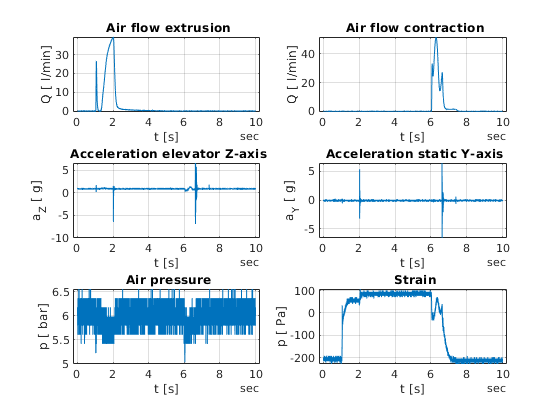

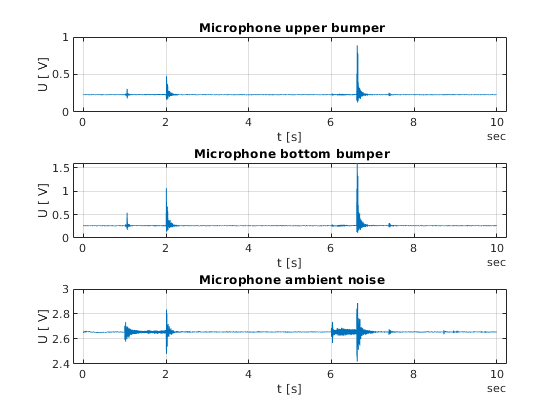

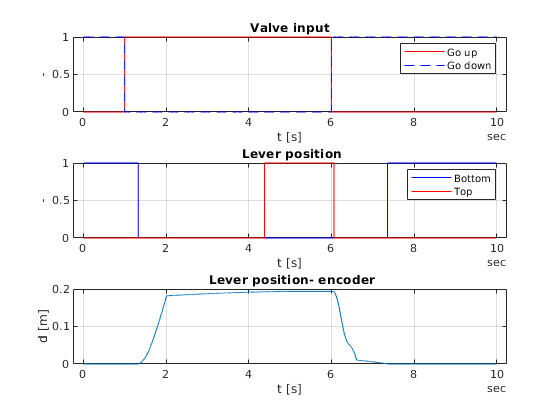

data_plot(data_test)

### Raw vs Preprocess

Some signals, such as Encoder, are very accurate. There is no preprocessing needed to apply. Signals noisier (Pressure signal or Strain) has to be preprocessed and applied some noise reduction algorithms. However, during experiments turned out that non preprocessed signals have better performance.  For example, the preprocessed Pressure classification model gives 78% accuracy; the raw pressure signal gives approximately 82%.

TODO add models

## Encoder

This sensor contain Lever Position. From this position velocity was calculated too. 

### Extracted features

encoder_cost = 25000;
encoder_suitability = 0.1;
addpath("sensor_encoder/")
features = load("sensor_encoder/LeverPosition_LeverVelocity_stat_features.mat").LeverPosition_LeverVelocity_stat_features;

We can rank features using Kruskall-Wallis analysis of variation to reduce number of features.

compute_ranking = 0;
if compute_ranking
    [~,encoder_ranked_features,~] = encoder_features_process(features);
else
    encoder_ranked_features = load("sensor_encoder/encoder_stat_features_ranked.mat").encoder_stat_features_ranked
end

encoder_ranked_features = 26×2 table
                  Features                   Kruskal-Wallis
    _____________________________________    ______________

    "LeverPosition_stats/RMS"                    1040.2    
    "LeverPosition_stats/Kurtosis"               825.07    
    "LeverPosition_stats/Mean"                   613.01    
    "LeverVelocity_stats/Mean"                   520.35    
    "LeverPosition_stats/ImpulseFactor"          507.99    
    "LeverPosition_stats/ClearanceFactor"        478.75    
    "LeverPosition_stats/Skewness"               434.76    
    "LeverPosition_stats/CrestFactor"            354.71    
    "LeverVelocity_stats/CrestFactor"            333.15    
    "LeverVelocity_stats/SINAD"                  284.75    
    "LeverVelocity_stats/Kurtosis"                277.3    
    "LeverPosition_stats/ShapeFactor"            258.33    
    "LeverPosition_stats/THD"                    228.3

Using only first 5 features *encoder_static_feature_model  *was trained.

Reduce extracted features for first five features.

first_five_features = encoder_ranked_features.Features(1:5);
reduced_features_with_label = [first_five_features;"Label"];
reduced_features = features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(reduced_features);

### Classification model based on encoder signals

Accuracy is 96.07 % 


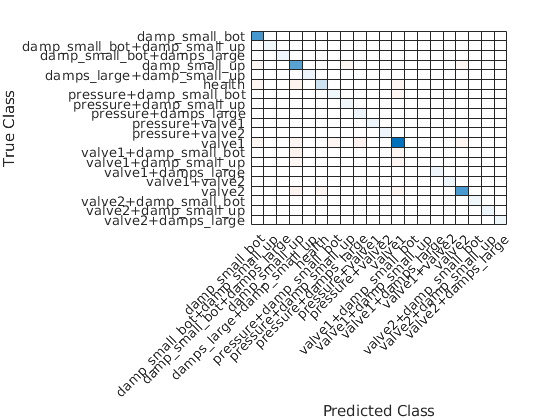

[encoder_model, ~] = encoder_FineKNN_train(train_data);
encoder_accuracy = confusion_matrix_plot_handler(encoder_model, test_data);

### Conclusion

It's possible to achieve 97 % accuracy, using only the first five ranked statistical features extracted from the system position signal.

results_table.("Encoder") = table(encoder_accuracy, encoder_cost, encoder_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Microphones

There are 3 microphones on stand. 

- Upper bamper microphone

- Bottom bamper micrphone

- Ambient microphone

mics_cost = 500*3;
mics_suitability = 1;
addpath("sensor_mics/")
features = load("sensor_mics/MICsFeaturesAll.mat").MICsFeaturesAll;
if compute_ranking
    [~,mics_ranked_features,~] = mics_features_process(features)
else
    mics_ranked_features = load("sensor_mics/mics_ranked_features.mat").mics_ranked_features
end

mics_ranked_features = 102×2 table
               Features                Kruskal-Wallis
    _______________________________    ______________

    "MIC_uBumper_stats/SNR"                1415.6    
    "MIC_Ambient_ps_spec/PeakAmp3"         783.19    
    "MIC_Ambient_stats/RMS"                697.96    
    "MIC_bBumper_ps_spec/PeakFreq4"        691.18    
    "MIC_uBumper_ps_spec/PeakAmp1"          677.7    
    "MIC_uBumper_stats/SINAD"              637.45    
    "MIC_Ambient_stats/Mean"               586.29    
    "MIC_bBumper_ps_spec/PeakFreq2"        573.66    
    "MIC_Ambient_ps_spec/BandPower"        566.55    
    "MIC_uBumper_ps_spec/BandPower"        521.97    
    "MIC_Ambient_ps_spec/PeakAmp8"         514.11    
    "MIC_Ambient_ps_spec/PeakAmp1"         504.39    
    "MIC_bBumper_ps_spec/PeakFreq1"        488.12    
    "MIC_uBumper_stats/RMS"                 470.3    
    "MIC_uBumper_stats/Mean"    

first_five_features = mics_ranked_features.Features(1:5)

first_five_features = 5×1 string array
    "MIC_uBumper_stats/SNR"
    "MIC_Ambient_ps_spec/PeakAmp3"
    "MIC_Ambient_stats/RMS"
    "MIC_bBumper_ps_spec/PeakFreq4"
    "MIC_uBumper_ps_spec/PeakAmp1"


Accuracy is 95.80 % 


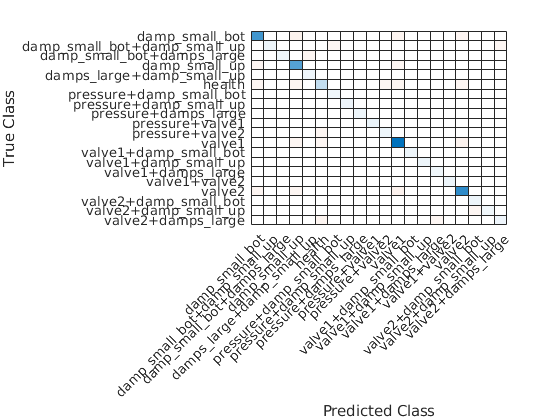

reduced_features_with_label = [first_five_features;"Label"];
reduced_features = features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(reduced_features);

[mics_model, ~ ] = mics_BaggedTrees_train(train_data);
mics_accuracy = confusion_matrix_plot_handler(mics_model, test_data);

### Conclusion

results_table.("Mics") = table(mics_accuracy, mics_cost, mics_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Flow Sensors

There are two signals measured:

- Flow Exrusion

- Flow Contraction

flow_cost = 12000;
flow_suitability = 0.5;

addpath("sensor_flow/");
features = load("sensor_flow/FlowsFeaturesAll.mat").FlowsFeaturesAll;
if compute_ranking
    [~,flow_ranked_features,~] = flow_features_process(features)
else
    flow_ranked_features = load("sensor_flow/flow_ranked_features.mat").flow_ranked_features
end

flow_ranked_features = 48×2 table
                 Features                  Kruskal-Wallis
    ___________________________________    ______________

    "FlowContraction_ps_spec/PeakAmp1"         1481.5    
    "FlowContraction_stats/CrestFactor"         967.6    
    "FlowContraction_ps_spec/PeakAmp3"         865.76    
    "FlowContraction_stats/Mean"               567.66    
    "FlowExtrusion_stats/SNR"                  558.11    
    "FlowContraction_ps_spec/PeakAmp4"         460.09    
    "FlowContraction_stats/Kurtosis"           424.03    
    "FlowExtrusion_stats/SINAD"                416.98    
    "FlowExtrusion_stats/CrestFactor"          379.85    
    "FlowContraction_ps_spec/PeakFreq3"        317.79    
    "FlowContraction_ps_spec/PeakAmp5"         279.82    
    "FlowExtrusion_stats/PeakValue"            247.64    
    "FlowExtrusion_ps_spec/PeakFreq2"          241.15    
    "FlowContraction_stats/

We will use only Flow Contraction signal:

reduced_features = [flow_ranked_features.Features(1:4); flow_ranked_features.Features(6)]

reduced_features = 5×1 string array
    "FlowContraction_ps_spec/PeakAmp1"
    "FlowContraction_stats/CrestFactor"
    "FlowContraction_ps_spec/PeakAmp3"
    "FlowContraction_stats/Mean"
    "FlowContraction_ps_spec/PeakAmp4"


Accuracy is 97.25 % 


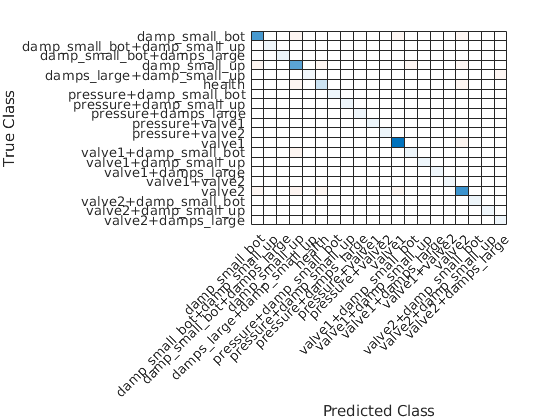

reduced_features_with_label = [reduced_features;"Label"];
reduced_features = features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(reduced_features);

[flow_model, ~ ] = train_flow_KNN(train_data);

flow_accuracy = confusion_matrix_plot_handler(flow_model, test_data);

### Conclusion

results_table.("Flow") = table(flow_accuracy, flow_cost, flow_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Accelerometer

There are two accelerometer sensors. Each sensor contains two signals in a perpendicular direction. 

One sensor is placed on the movable part of the stand device. The second is on the statical part of the stand device.

acc_cost = 3500*2;
acc_suitability = 0.5;

addpath("sensor_acc/");
features = load("sensor_acc/AccAllFeatures.mat").AccAllFeatures;
if compute_ranking
    [~,acc_ranked_features,~] = acc_features_process(features)
else
    acc_ranked_features = load("sensor_acc/acc_ranked_features.mat").acc_ranked_features
end

acc_ranked_features = 136×2 table
                      Features                       Kruskal-Wallis
    _____________________________________________    ______________

    "AccelerometerStatic_axisY_stats/ShapeFactor"        1028.1    
    "AccelerometerStatic_axisZ_ps_spec/PeakAmp3"            577    
    "AccelerometerStatic_axisY_stats/RMS"                474.61    
    "AccelerometerStatic_axisZ_ps_spec/PeakAmp10"        391.59    
    "AccelerometerMoving_axisZ_stats/Skewness"           366.26    
    "AccelerometerStatic_axisZ_ps_spec/PeakAmp4"         339.08    
    "AccelerometerStatic_axisZ_ps_spec/PeakAmp5"         319.64    
    "AccelerometerStatic_axisZ_ps_spec/PeakAmp1"         318.32    
    "AccelerometerStatic_axisY_stats/Std"                   296    
    "AccelerometerStatic_axisY_ps_spec/BandPower"        286.32    
    "AccelerometerStatic_axisZ_ps_spec/PeakAmp2"         279.53    
    "Accelero

Accuracy is 75.00 % 


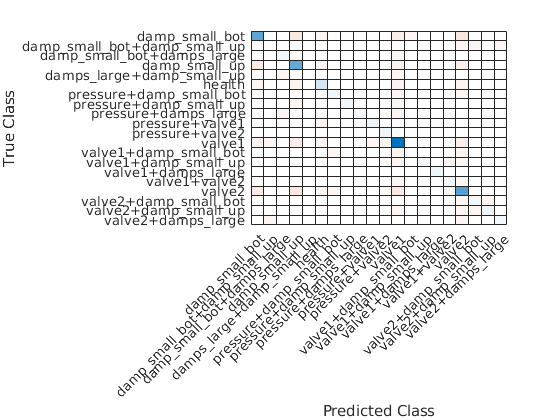


reduced_features = acc_ranked_features.Features(1:5);
reduced_features_with_label = [reduced_features;"Label"];
reduced_features = features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(reduced_features);

[acc_model, ~ ] = acc_BaggedTrees_KW_train(train_data);

acc_accuracy = confusion_matrix_plot_handler(acc_model, test_data);

Accuracy is 91.60 % 


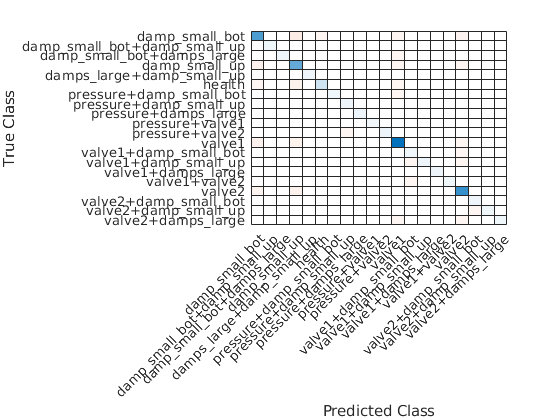

reduced_features = acc_ranked_features.Features(1:50);
reduced_features_with_label = [reduced_features;"Label"];
reduced_features = features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(reduced_features);

[acc_model, ~ ] = acc_BaggedTrees_50_features_train(train_data);

acc_accuracy = confusion_matrix_plot_handler(acc_model, test_data);

### Conclusion

results_table.("Accelerometer") = table(acc_accuracy, acc_cost, acc_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Pressure Sensor

pressure_cost = 1000;
pressure_suitability = 0.5;

addpath("sensor_pressure/");
features = load("sensor_pressure/PressureAllFeatures.mat").PressureAllFeatures;

if compute_ranking
    [~,pressure_ranked_features,~] = pressure_features_process(features)
else
    pressure_ranked_features = load("sensor_pressure/pressure_ranked_features.mat").pressure_ranked_features
end

pressure_ranked_features = 34×2 table
                 Features                  Kruskal-Wallis
    ___________________________________    ______________

    "AirPressure_stats/Std"                      1147    
    "AirPressure_stats/ShapeFactor"            504.11    
    "AirPressure_stats/Kurtosis"               321.83    
    "AirPressure_stats/PeakValue"              249.09    
    "AirPressure_stats/SINAD"                  198.65    
    "AirPressure_stats/ClearanceFactor"        172.61    
    "AirPressure_stats/RMS"                    164.29    
    "AirPressure_stats/ImpulseFactor"           146.5    
    "AirPressure_stats/SNR"                    143.56    
    "AirPressure_stats/Mean"                   131.61    
    "AirPressure_stats/CrestFactor"            128.47    
    "AirPressure_ps_spec/BandPower"            121.59    
    "AirPressure_ps_spec/PeakAmp1"             110.29    
    "AirPressure_stats/

Best result was achieved using all features without PCA.

Accuracy is 76.65 % 


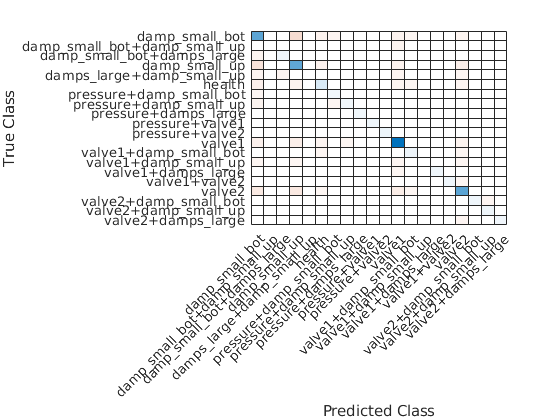

[train_data, test_data] = split_dataset(features);
[pressure_model, ~ ] = pressure_BaggedTrees_AllFeatures_train(train_data);
pressure_accuracy = confusion_matrix_plot_handler(pressure_model, test_data);

### Conclusion

results_table.("Pressure") = table(pressure_accuracy, pressure_cost, pressure_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Proximity Sensors

proximity_cost = 1000*2;
proximity_suitability = 0.5;

addpath("sensor_proximity/");
features = load("sensor_proximity/ProximityAllFeatures.mat").ProximityAllFeatures;

if compute_ranking
    [~,proximity_ranked_features,~] = proximity_features_process(features)
else
    proximity_ranked_features = load("sensor_proximity/proximity_ranked_features.mat").proximity_ranked_features
end

proximity_ranked_features = 26×2 table
                       Features                       Kruskal-Wallis
    ______________________________________________    ______________

    "ProximitySensor_bottom_stats/SINAD"                     NaN    
    "ProximitySensor_bottom_stats/SNR"                       NaN    
    "ProximitySensor_bottom_stats/THD"                       NaN    
    "ProximitySensor_bottom_stats/ClearanceFactor"        654.56    
    "ProximitySensor_bottom_stats/CrestFactor"            654.56    
    "ProximitySensor_bottom_stats/ImpulseFactor"          654.56    
    "ProximitySensor_bottom_stats/ShapeFactor"            654.56    
    "ProximitySensor_bottom_stats/Skewness"               654.53    
    "ProximitySensor_bottom_stats/Kurtosis"               606.46    
    "ProximitySensor_bottom_stats/Mean"                   601.02    
    "ProximitySensor_bottom_stats/RMS"                    601.02

Best result was achieved using all features without PCA.

Accuracy is 80.51 % 


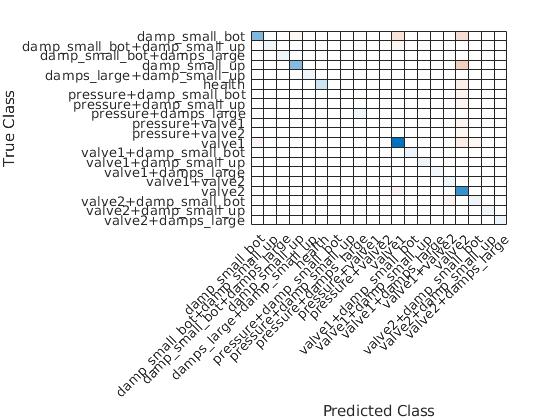

[train_data, test_data] = split_dataset(features);

[proximity_model, ~ ] = proximity_BaggedTrees_AllFeatures_train(train_data);

proximity_accuracy = confusion_matrix_plot_handler(proximity_model, test_data);

### Conclusion

results_table.("Proximity") = table(proximity_accuracy, proximity_cost, proximity_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Strain Gauge

straingauge_cost = 15000;
straingauge_suitability = 0.5;

addpath("sensor_strain/");
features = load("sensor_strain/StrainAllFeatures.mat").StrainAllFeatures;

if compute_ranking
    [~,strain_ranked_features,~] = strain_features_process(features)
else
    strain_ranked_features = load("sensor_strain/strain_ranked_features.mat").strain_ranked_features
end

strain_ranked_features = 34×2 table
                 Features                  Kruskal-Wallis
    ___________________________________    ______________

    "StrainGauge_stats/ClearanceFactor"        821.78    
    "StrainGauge_stats/SNR"                    550.95    
    "StrainGauge_stats/ShapeFactor"            393.57    
    "StrainGauge_stats/Std"                    345.13    
    "StrainGauge_stats/ImpulseFactor"          333.92    
    "StrainGauge_stats/Kurtosis"               284.45    
    "StrainGauge_stats/SINAD"                  279.39    
    "StrainGauge_ps_spec/PeakAmp3"             275.89    
    "StrainGauge_ps_spec/BandPower"            265.14    
    "StrainGauge_stats/CrestFactor"            257.88    
    "StrainGauge_ps_spec/PeakAmp1"             234.89    
    "StrainGauge_stats/RMS"                    211.74    
    "StrainGauge_stats/Mean"                   205.26    
    "StrainGauge_ps_spec/

Accuracy is 95.04 % 


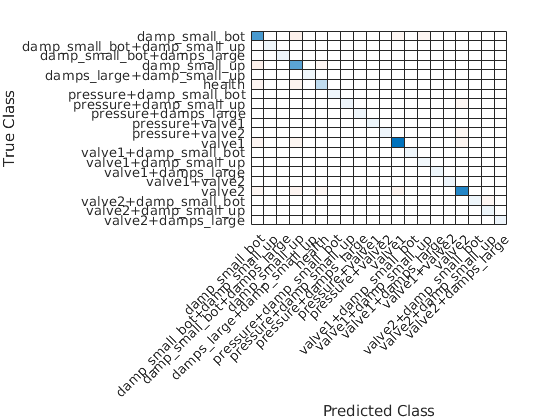

reduced_features = strain_ranked_features.Features(1:5);
reduced_features_with_label = [reduced_features;"Label"];
reduced_features = features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(reduced_features);

[strain_model, ~ ] = strain_BaggedTrees_anova_train(train_data);

straingauge_accuracy = confusion_matrix_plot_handler(strain_model, test_data);

### Conclusion

results_table.("Strain") = table(straingauge_accuracy, straingauge_cost, straingauge_suitability, 'VariableNames', {'Perfomance', 'Cost', 'Suitability'});

## Temperature Sensors

Temperature sensors do only one measurement during the experiment. 

These values can be represented as features. Plotting random data from the dataset shows that they correlated to Ambient temperature different in different measurement days. These data are sensitive to ambient conditions. The classification model trained on this data not robust in real life.

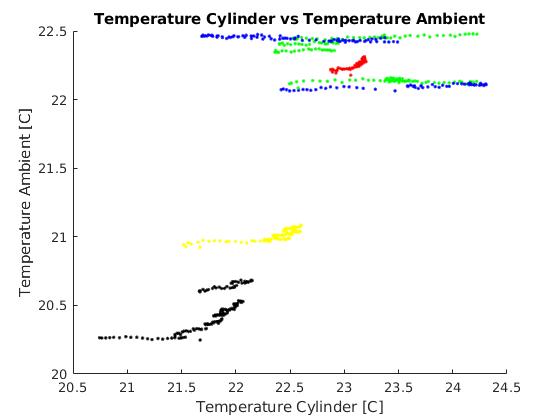

temp_features = load("featuretable/temp_features.mat").temp_features;
figure
hold on
for i = 1:size(temp_features)
    var = temp_features(i,:);
    label = var.Label;
    temp_cylinder = var.Temp_Cylinder;
    temp_ambient = var.Temp_Ambient;
    switch label
        case "health"
            plot(temp_cylinder, temp_ambient, 'r.')
        case "valve1"
            plot(temp_cylinder, temp_ambient, 'g.')
        case "valve2"
            plot(temp_cylinder, temp_ambient, 'b.')
        case "damp_small_bot"
            plot(temp_cylinder, temp_ambient, 'k.')
        case "damp_small_up"
            plot(temp_cylinder, temp_ambient, 'y.')
    end
end
title("Temperature Cylinder vs Temperature Ambient")
xlabel("Temperature Cylinder [C]")
ylabel("Temperature Ambient [C]")

## Conclusion

result_table = struct2table(results_table);
sensors_efficiency = table();
perf_coef = 1;  % TODO
cost_coef = 1;  % TODO
suit_coef = 1;  % TODO

for sensor = result_table.Properties.VariableNames
    disp(string(sensor))
    var = result_table.(string(sensor))
    sensors_efficiency.(string(sensor)) = perf_coef*var.Perfomance+cost_coef*var.Cost+suit_coef*var.Suitability;
end

Encoder


var = 1×3 table
    Perfomance    Cost     Suitability
    __________    _____    ___________

     0.96074      25000        0.1    


Mics


var = 1×3 table
    Perfomance    Cost    Suitability
    __________    ____    ___________

     0.95799      1500         1     


Flow


var = 1×3 table
    Perfomance    Cost     Suitability
    __________    _____    ___________

     0.97245      12000        0.5    


Accelerometer


var = 1×3 table
    Perfomance    Cost    Suitability
    __________    ____    ___________

     0.91598      7000        0.5    


Pressure


var = 1×3 table
    Perfomance    Cost    Suitability
    __________    ____    ___________

     0.76653      1000        0.5    


Proximity


var = 1×3 table
    Perfomance    Cost    Suitability
    __________    ____    ___________

      0.8051      2000        0.5    


Strain


var = 1×3 table
    Perfomance    Cost     Suitability
    __________    _____    ___________

     0.95041      15000        0.5    


sensors_efficiency

sensors_efficiency = 1×7 table
    Encoder    Mics    Flow     Accelerometer    Pressure    Proximity    Strain
    _______    ____    _____    _____________    ________    _________    ______

     25001     1502    12001       7001.4         1001.3      2001.3      15001 


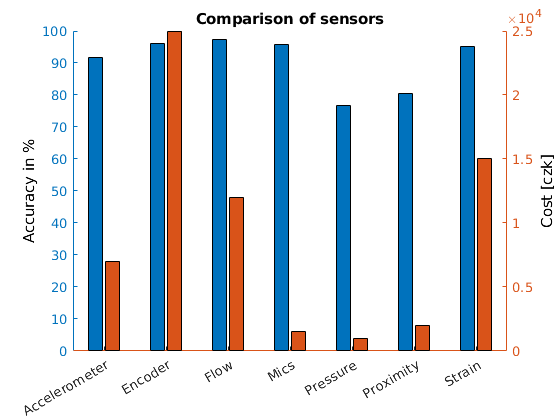


x = [];
y1 = [];
y2 = [];
for sensor = result_table.Properties.VariableNames
    x = [x string(sensor)];
    var = result_table.(string(sensor));
    y1 = [y1;var.Perfomance];
    y2 = [y2;var.Cost];
end
x = categorical(x');
y1 = double([y1 zeros(7,1)])*100;
y2 = double([zeros(7,1) y2]);

figure
hold on
yyaxis left
b1 = bar(x,y1);
ylabel("Accuracy in %", 'Color', 'k')

yyaxis right
b2 = bar(x,y2);
ylabel("Cost [czk]", 'Color', 'k')
hold off
title("Comparison of sensors")

function [dataTrain, dataTest] = split_dataset(data)
    cv = cvpartition(size(data,1), 'HoldOut', 0.3);
    idx = cv.test;      
    dataTrain = data(~idx, :);
    dataTest = data(idx, :);
end

function [accuracy] = confusion_matrix_plot_handler(mdl, features)
    required_features = mdl.RequiredVariables;
    targetLabels = features(:,"Label");
    inputTable = features(:, required_features);
    predictedLabels = mdl.predictFcn(inputTable);
    [C,order] = confusionmat(table2array(targetLabels),predictedLabels);
    accuracy = sum(table2array(targetLabels) == predictedLabels)/numel(predictedLabels);
    fprintf("Accuracy is %0.2f %% \n", accuracy*100)
    figure
    confusionchart(C, order)
end